# Trabalho 6 - Realimentação de estados

## Nome: Luiza Batista Laquini

## Data limite para entrega: 13/12, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- O trabalho não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entregue no prazo o que estiver pronto.

I=21;
[G,ts0,sat]=init_t6(I);

**Atividade 1) **Obtenha a realimentação de estados tal que a saída tenha sobreelevação $UP\leq 4.3\%$ e o tempo de estabelecimento  $t_s\leq ts_0$. Deve-se ajustar o ganho da FT de malha fechada de modo que a saída tenda para a referência unitária.  

Faz parte da resposta:

- Explicar como escolheu os polos de malha fechada. 

- Mostrar e explicar a saída de malha aberta e a de malha fechada, o sinal de controle, a FT de malha fechada.

- Comentar o sinal de controle e seu valor em regime.

Verificando o valor de ts0:

ts0

ts0 = 0.3325

Passando G para o espaço de estados:

Gss = ss(G)

Gss =
 
  A = 
          x1     x2     x3
   x1    -13     -4  -1.25
   x2      8      0      0
   x3      0      2      0
 
  B = 
        u1
   x1  0.5
   x2    0
   x3    0
 
  C = 
           x1      x2      x3
   y1       0       0  0.8333
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


A = [-13 -4 -1.25; 8 0 0; 0 2 0];
B = [0.5; 0; 0];
C = [0 0 0.8333];
D = 0;

Primeiro, devemos verificar se o sistema é controlável. Para isso, seja o sistema:


$$\overset{\ldotp }{x} =\textrm{Ax}+\textrm{Bu}$$



$$y\;=\textrm{Cx}+\textrm{Du}$$


Ele será controlável se seu estado pode ser levado de x(0) a x(t) em um tempo finito t através da entrada u(t). Para isso:

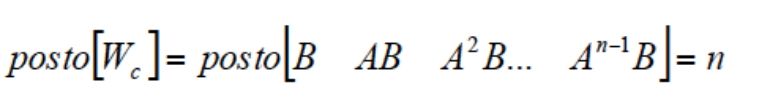, onde n é a ordem do sistema e Wc é chamada de matriz de controlabilidade.

A matriz Wc é quadrada para o caso de 1 entrada. Já para m entradas, Wc tem ordem n.(m*n)

Verificando se o sistema é controlável:

Wc = [B A*B A*A*B]

Wc =     0.5000   -6.5000   68.5000
         0    4.0000  -52.0000
         0         0    8.0000


det(Wc)

ans = 16

O determinante de Wc é diferente de zero, com isso podemos confirmar que o posto será igual a ordem do sistema, conclui-se, portanto, que o sistema é controlável. Ou seja, todos estados são afetados pela entrada.

Podemos, ainda, comprovar o posto com o uso do comando "rank"

posto = rank(Wc)

posto = 3

Aplicando-se a lei de controle $u\left(t\right)=r\left(t\right)-\textrm{Kx}\left(t\right)$ no sistema já descrito


$$\begin{array}{l}
\overset{\ldotp }{x} =\textrm{Ax}+\textrm{Bu}\\
y\;=\textrm{Cx}+\textrm{Du}
\end{array}$$
 
$$\to$$
  
$$\begin{array}{l}
\overset{\ldotp }{x} =\textrm{Ax}+B\left(r-\textrm{Kx}\right)\\
y\;=\textrm{Cx}+D\left(r-\textrm{Kx}\right)
\end{array}$$

$$\to$$
  
$$\begin{array}{l}
\overset{\ldotp }{x} =\left(A-\textrm{BK}\right)x+\textrm{Br}\\
y\;=\left(C-\textrm{DK}\right)x+\textrm{Dr}
\end{array}$$


O autovalores da nova matriz do sistema (A-BK) são alterados pela matriz de ganho K.

Observa-se que pela escolha adequada dos ganhos pode-se obter qualquer polinômio característico de malha fechada, com as raízes que se desejar. Em outras palavras, os autovalores, que são os polos malha fechada, podem ser livremente escolhidos a partir dos ganhos do vetor K, tal que:


$$|\textrm{SI}-\left(A-\textrm{BK}\right)|=\left(s+\textrm{p1}\right)\left(s+\textrm{p2}\right)\left(s+\textrm{p3}\right)$$


Escolhendo, então, a posição dos polos de acordo com as especificações.

UP = 4.2; % menor que 4.3%
ts = 0.3; % menor que 0.3325
a = log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2))

zeta = 0.7103

wn = 4/(zeta*ts)

wn = 18.7716

Com isso, para podermos definir os polos p1 e p2, podemos substituir em $s^{2\;} +2\zeta w_{n\;} s+w_n^2$. Para p3 devemos posicioná-lo à esquerda do par de polos e , de forma que seja um polo rápido e que não atrapalhe a influência dos par.

r=roots([1 2*zeta*wn wn^2])

r =  -13.3333 +13.2135i
 -13.3333 -13.2135i


Com p1 e p2 definidos podemos verificar se foram atendidas as especificações de tempo de estabilização e sobre-impulso olhando a função de transferência gerada por elas:

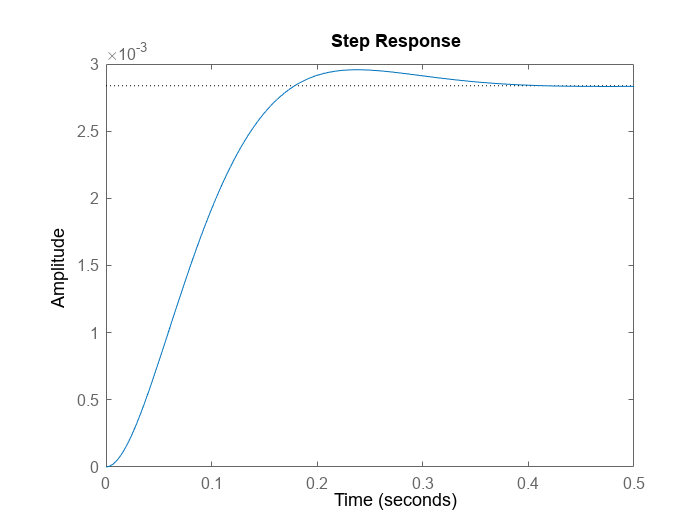

p1 = r(1);
p2 = r(2);
G1 = tf(1, poly([p1 p2]));
step(G1)

stepinfo(G1)

ans = struct with fields:
         RiseTime: 0.1150
    TransientTime: 0.3172
     SettlingTime: 0.3172
      SettlingMin: 0.0026
      SettlingMax: 0.0030
        Overshoot: 4.1998
       Undershoot: 0
             Peak: 0.0030
         PeakTime: 0.2383


É possível ver que as especificações de overshoot e de tempo de estabelecimento foram atendidas.

Para prosseguir, será colocado p3 = -20, porque isso é mais rápido do que p1 e p2.

p3 = -20;
K=place(A, B, [p1 p2 p3]);

Sistema em malha fechada:

s1mf = ss(A-B*K, B, C, D);

Função de transferência de malha fechada (FTMF):

g1mf=tf(s1mf)

g1mf =
 
               6.666
  --------------------------------
  s^3 + 46.67 s^2 + 885.7 s + 7047
 
Continuous-time transfer function.
Model Properties


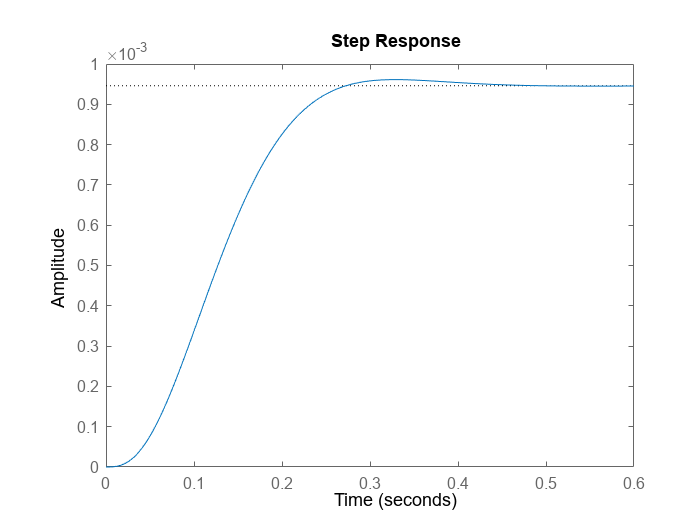

step(g1mf)

stepinfo(g1mf)

ans = struct with fields:
         RiseTime: 0.1549
    TransientTime: 0.2515
     SettlingTime: 0.2515
      SettlingMin: 8.5459e-04
      SettlingMax: 9.6127e-04
        Overshoot: 1.6221
       Undershoot: 0
             Peak: 9.6127e-04
         PeakTime: 0.3281


Temos agora os 3 polos e as especificações de overshoot e de tempo de estabelecimento atendidas, porém, ainda deve-se ajustar o ganho da FT de malha fechada de modo que a saída tenda para a referência unitária.

Ao clicar em cima da imagem é possível ver que a referência está aproximadamente em 0.000945312. Para que esse valor passe a ser 1, adiciona-se um ganho proporcional direto na FT do controlador, descrito como K1:

valor_regime = 0.000945312;
K1 = 1 / valor_regime

K1 = 1.0579e+03

s1mf_nova=K1*ss(A-B*K,B,C,D);
g1mf_nova=tf(s1mf_nova)

g1mf_nova =
 
                7052
  --------------------------------
  s^3 + 46.67 s^2 + 885.7 s + 7047
 
Continuous-time transfer function.
Model Properties


Simulando novamente:

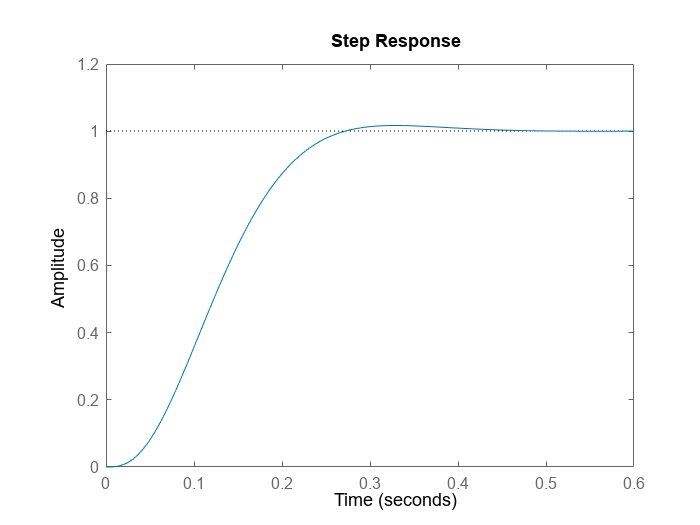

step(g1mf_nova)

stepinfo(g1mf_nova)

ans = struct with fields:
         RiseTime: 0.1549
    TransientTime: 0.2515
     SettlingTime: 0.2515
      SettlingMin: 0.9040
      SettlingMax: 1.0169
        Overshoot: 1.6221
       Undershoot: 0
             Peak: 1.0169
         PeakTime: 0.3281


Portanto, temos todas as especificações atendidas:

- ts = 0.2515 (<0.3325) 

- UP = 1.6221 (<4.3%)

- Saída tendendo a referência unitária para malha fechada

Agora, vamos verificar o sinal de controle:

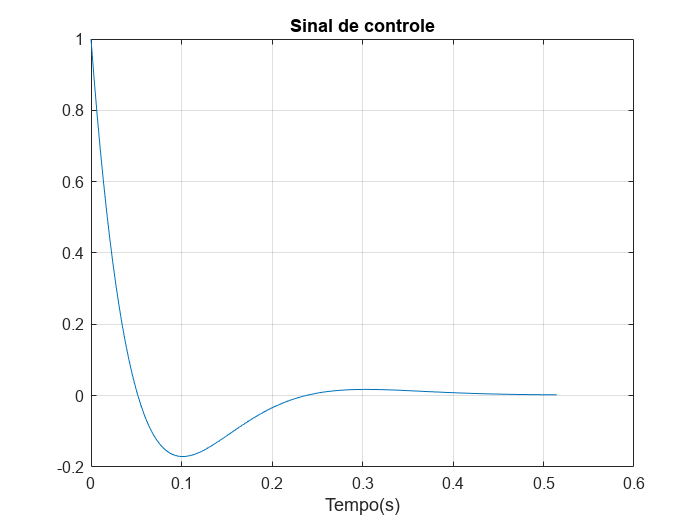

[y1,t1,x1]=step(s1mf);
u1=1-K*(x1');
figure;plot(t1,u1);grid
title('Sinal de controle');
xlabel('Tempo(s)');

O sistema chega ao regime após um pico do sinal de controle e o controlador não faz mais 'esforços' para mantê-lo, significa que obtemos um sistema estável e eficiente, sem necessidade de mais correções.

**Atividade 2)** Nesta atividade usa-se o controlador anterior mas o sinal de controle está limitado por uma saturação** sat.** Use a função [y,t,u] = simula_t6(s1,K,p1,sat)  para simulação com a saturação e obter os valores de y,u,t. Verifique se sob saturação a especificação é atendida. Caso não, altere a localização dos polos de malha fechada, lembrando que respostas mais rápidas exigem um sinal de controle de maior amplitude.

Na função simula_t6:

- s1 : sistema em variáveis de estado utilizado em malha aberta

- K: realimentação de estados calculada para s1

- p1: ganho multiplicado pela referência para fazer a saída tender a 1 em regime

- sat: valor máximo (em módulo) que o sinal de controle pode assumir.

Faz parte da resposta:

- Plotar a saída sem e com saturação mostrando o atendimento da especificação

- Plotar e interpretar o sinal de controle sem e com saturação

- Explicar o efeito da saturação e como foi resolvido.

Usando a função fornecida:

[y2,t2,u2] = simula_t6(Gss,K,valor_regime,sat);

Simulando a resposta sem saturação versus com saturação:

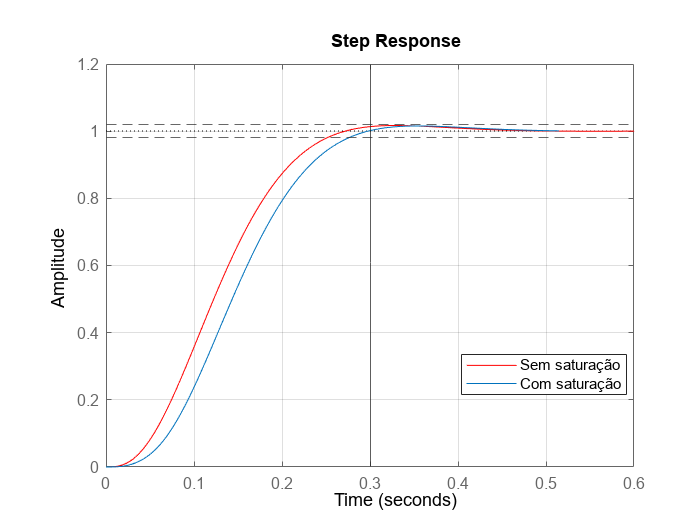

figure;hold on; 
step(g1mf_nova, 'r');
plot(t2,y2);yline(1.02, '--');yline(0.98, '--');xline(ts);grid on;
legend('Sem saturação', 'Com saturação', "Position", [0.65837,0.24579,0.2375,0.082143]);
hold off;

As curvas são semelhantes, sendo a curva com saturação um pouco mais lenta. O print abaixo mostra um zoom do plot acima para melhor visualização dos parâmetros sendo atendidos:

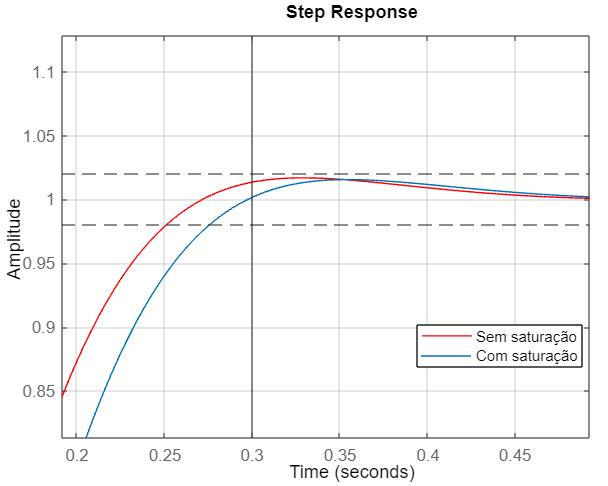

Com ts sendo mostrado por uma linha vertical e as funções passando dentro das linhas 1.02 e 0.98, que correspondem ao desvio de 2%, vemos que as especificações são atendidas para UP e ts.

Agora verificando o sinal de controle:

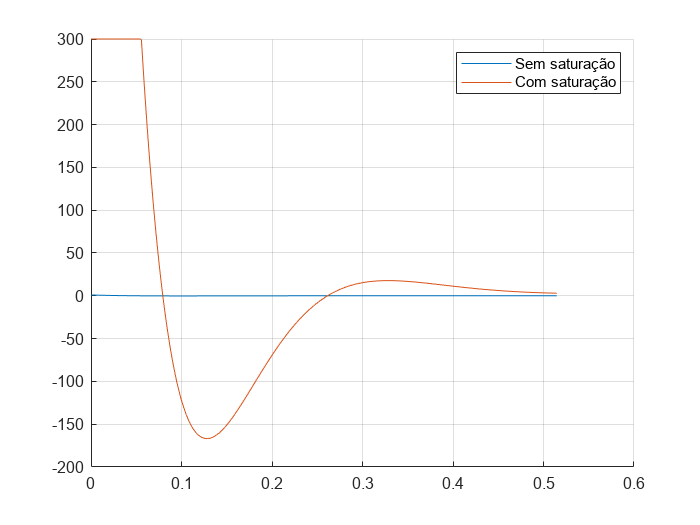

figure;hold on; 
plot(t1,u1);plot(t2,u2), grid on;
legend('Sem saturação', 'Com saturação');
hold off;

A saturação atua como um limite no sinal de controle, por esse motivo o pico inicial do sinal de controle com saturação é cortado.

O sinal de controle sem saturação é tão pequeno quando comparado ao com saturação que aparenta até mesmo ser uma linha reta no gráfico. Na realidade, como já mostrado anteriormente, ele apenas possui uma magnitude bem mais baixa quando comparada com o sinal de controle que possui saturação. 

Print do plot realizado anteriormente que comprova isso:

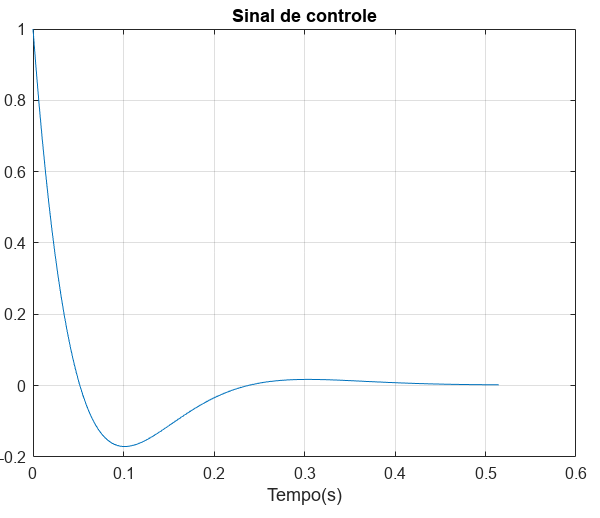

**Atividade 3) **Projetar uma realimentação integral de estados de forma que o erro para entrada degrau seja zero com a mesma especificação de UP e Ts do item 1. Neste caso, usa-se p1=1, pois a realimentação integral resolve o problema do erro em regime.

Faz parte da resposta:

- Plotar e interpretar a saída, o sinal de controle e os estados, mostrando o atendimento da especificação.

- Comentar o sinal de controle e seu valor em regime.

- Apresentar a FT de malha fechada e explicar por que o erro em regime para entrada degrau torna-se nulo.

A estratégia de realimentação integral de estados visa conseguir erro nulo em regime para entrada em degrau usando alimentação de estados. O integrador adiciona um polo a mais (um estado a mais) no sistema. Devido a isto, deve-se escolher mais um polo para ser alocado, que deve ser mais rápido que os demais.

É necessário contruir o sistema aumentado, ou seja, com um estado adicional devido ao polo na origem. Agora o sistema terá 4 estados. 

A1=[A [0;0;0];[-C 0]];
B1=[B;0];
Br=[0 ;0;0;1]; 
C1=[C 0];
D1=D;
sima=ss(A1,B1,C1,D1);

Alocando o quarto polo:

Nosso polo mais rápido até o momento é o p3 em -20

O quarto polo (p4) será adicionado então em -30, mais rápido do que o p3.

p4 = -30;
K3 = place(A1, B1, [p1 p2 p3 p4])

K3 = 1.0e+04 *

    0.0127    0.0563    0.4200   -3.1715


Sistema em malha fechada:

simf=ss(A1-B1*K3,Br,C1,D1)

simf =
 
  A = 
              x1         x2         x3         x4
   x1     -76.67     -285.7      -2101  1.586e+04
   x2          8          0          0          0
   x3          0          2          0          0
   x4          0          0    -0.8333          0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
           x1      x2      x3      x4
   y1       0       0  0.8333       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


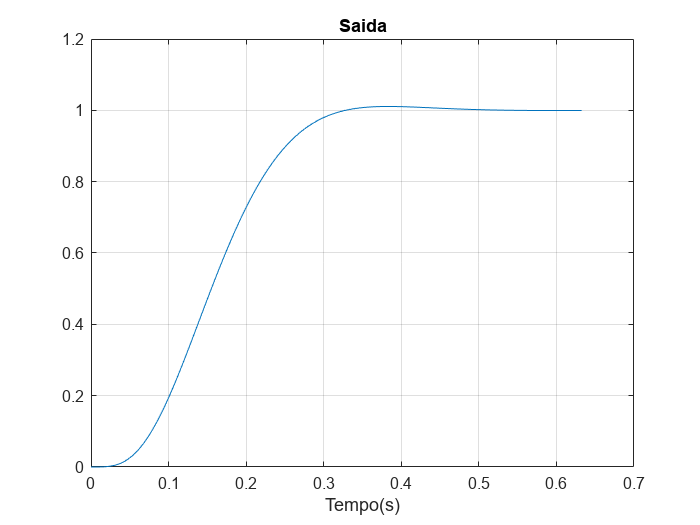

[y3,t3,x3]=step(simf);
u3=1-K3*(x3');
figure;plot(t3,y3);grid;
title('Saida');xlabel('Tempo(s)');

stepinfo(simf)

ans = struct with fields:
         RiseTime: 0.1732
    TransientTime: 0.3002
     SettlingTime: 0.3002
      SettlingMin: 0.9012
      SettlingMax: 1.0108
        Overshoot: 1.0849
       Undershoot: 0
             Peak: 1.0108
         PeakTime: 0.3838


Observando a resposta e as informações de "stepinfo", é possível ver que as especificações foram atendidas:

- ts = 0.3002 (<0.3325)

- UP = 1.0849 (<4.3%)

- Erro nulo, devido ao integrador

Pode-se afirmar então que com a adição de p4, o erro em regime é nulo, por se tratar de uma realimentação integral e as especificações que são controladas por p1 e p2 são mantidas, já que p4 é um polo ainda mais rápido que p3, que também não interfere na resposta.

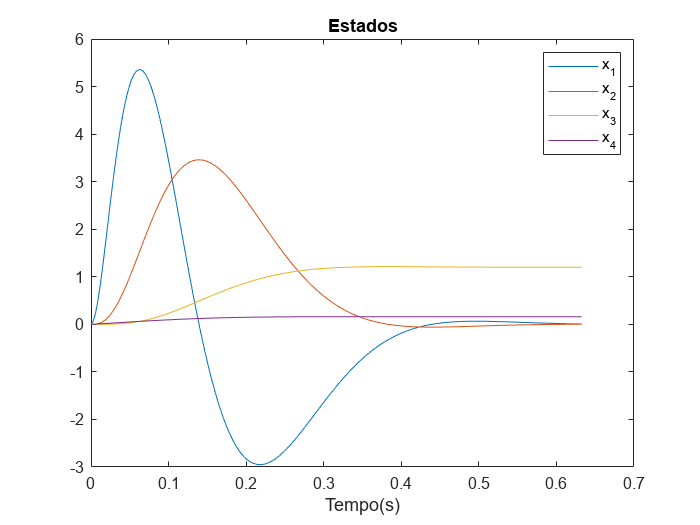

figure;
plot(t3,x3);legend('x_1','x_2','x_3','x_4');
title('Estados');xlabel('Tempo(s)');

São exibidos 4 estados ao longo do tempo. O estado x1 representa o maior pico de resposta e a maior oscilação, podendo representar uma variável de saída ou um erro que é corrigido rapidamente. x2 e x3 são menos oscilatórios podendo ser estados internos. Já x4 se mantem constante, o que muito provavelmente se trata do integrador adicionado para garantir o erro nulo.

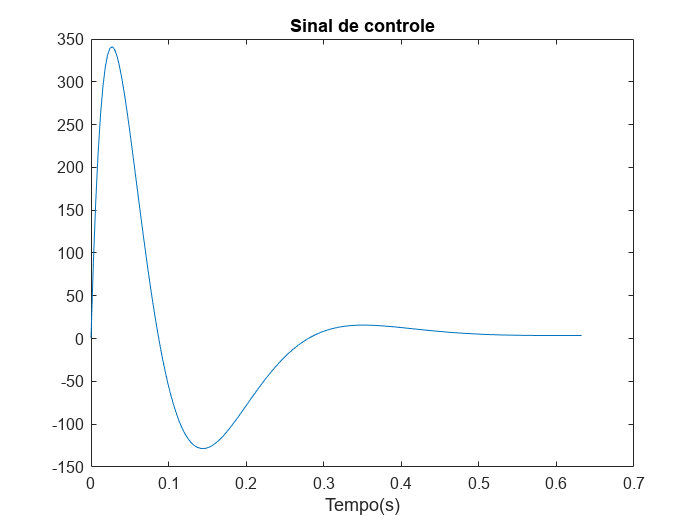

figure;
plot(t3,u3);
title('Sinal de controle');
xlabel('Tempo(s)');

Verifica-se um pico inicial que leva o sistema ao 'cenário' desejado. O valor em regime é possível de ser visualizado clicando em cima do gráfico, está em torno de 1.74, que é próximo de zero.

**Atividade 4) **Nesta atividade usa-se o controlador anterior mas o sinal de controle está limitado pela saturação** sat.** Use a função [y,t,u] = simula_t6(s1a, KI,1,sat)  para simulação com a saturação e obter os valores de y,u,t, sendo que s1a é o sistema aumentado e KI é a realimentação integral de estados. Verifique se sob saturação a especificação é atendida. Caso não, altere a localização dos polos de malha fechada, lembrando que respostas mais rápidas exigem um sinal de controle de maior amplitude.

Faz parte da resposta:

- Plotar a saída sem e com saturação mostrando o atendimento da especificação

- Plotar e interpretar o sinal de controle sem e com saturação

- Explicar como foi feita a escolha dos polos de malha fechada tendo em vista a saturação.

Usando a função fornecida:

[y4,t4,u4] = simula_t6(sima,K3,1,sat);

Simulando a resposta sem saturação versus com saturação:

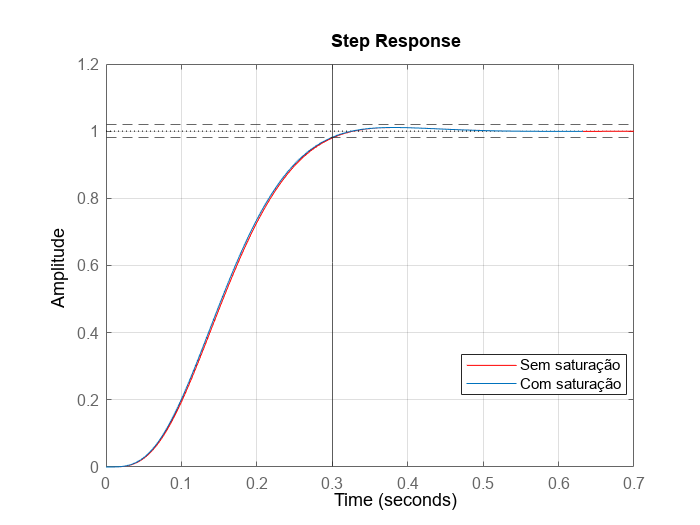

figure;hold on; 
step(simf, 'r');
plot(t4,y4);yline(1.02, '--');yline(0.98, '--');xline(ts);grid on;
legend('Sem saturação', 'Com saturação', "Position", [0.65837,0.24579,0.2375,0.082143]);
hold off;

As curvas são bastante semelhantes. O print abaixo mostra um zoom do plot acima para melhor visualização dos parâmetros sendo atendidos:

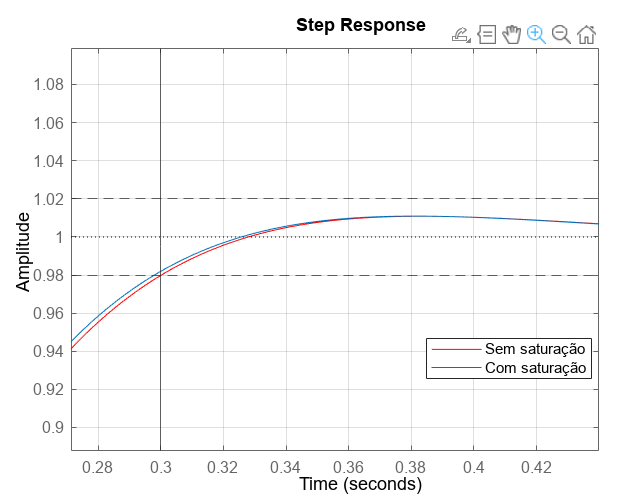

Com ts sendo exibido por uma linha vertical e as funções passando dentro das linhas 1.02 e 0.98, que correspondem ao desvio de 2%, vemos que as especificações são atendidas para UP e ts.

Agora, verificando o sinal de controle:

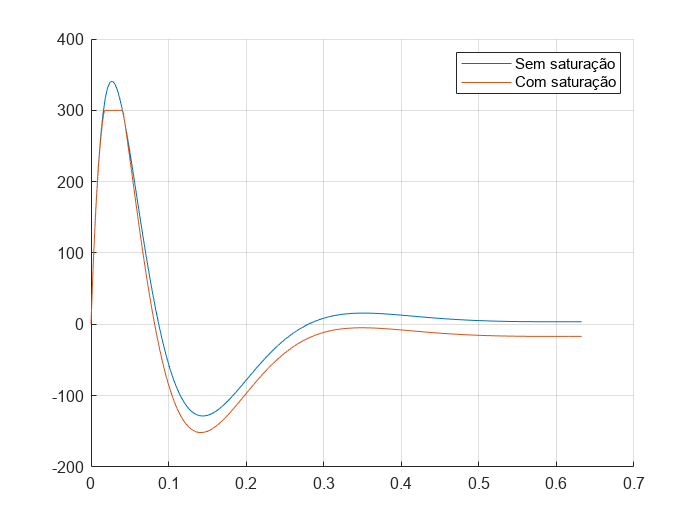

figure;hold on; 
plot(t3,u3);plot(t4,u4), grid on;
legend('Sem saturação', 'Com saturação');
hold off;

Observa-se que com a saturação em 300, o sinal de controle saturado não ultrapassa esse valor, configurando um limite, enquanto o sinal de controle sem saturação o faz. Além disso, nota-se que o sinal de controle sem saturação estabiliza um pouco mais próximo de zero do que o sinal com saturação, isso significa que a saturação exige um pouco mais de 'esforço' do controlador em regime para manter a estabilidade do sistema.

A escolha dos polos em um sistema de controle de realimentação integral de estados com saturação envolve um equilíbrio cuidadoso entre atender às especificações de desempenho desejadas e garantir que o sistema seja robusto e eficiente nas condições físicas dadas pela saturação.